# **Metoda oparta na interpolacji Lagrange'a**

clearvars all; close all;

f = @(x) x + x.^(-2);
x = 1:0.05:2;
epsi = 1e-2; gamma = 1e-4;
l = 1; r = 2;
Nmax = 100;

[x_res, iter] = lagrange(f, l, r, epsi, gamma, Nmax)

x_res = 1.2600

iter = 11

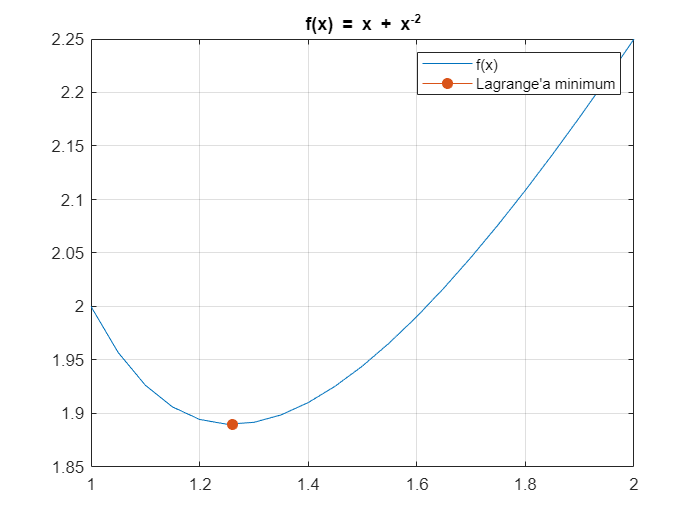


figure()
plot(x, f(x), 'DisplayName', 'f(x)'); hold on; grid on;
plot(x_res, f(x_res), 'Marker', '.', 'MarkerSize', 20, 'DisplayName', "Lagrange'a minimum");
title("f(x) = x + x^{-2}"); legend();

x = -0.3:0.005:0.1;
px = [-10 -5 0 5 10]; py = [0.0001 -0.1 0 0.1 -0.0001]; stopien=5;
W = polyfit(px, py, stopien);
f = @(x) (0.001*sin(x/10)).*(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))+0.000001*x;

epsi = 0.05; gamma = 0.0063;
l = -0.2750; r = 0.0063;
Nmax = 100;

[x_res, iter] = lagrange(f, l, r, epsi, gamma, Nmax)

x_res = -0.1004

iter = 3

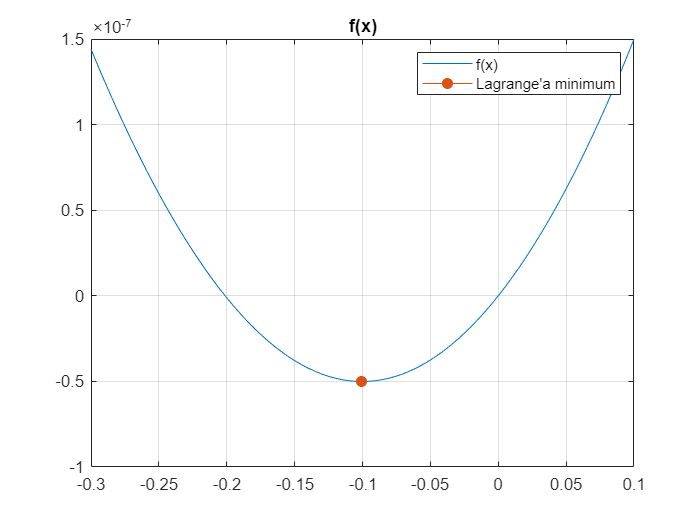


figure()
plot(x, f(x), 'DisplayName', 'f(x)'); hold on; grid on;
plot(x_res, f(x_res), 'Marker', '.', 'MarkerSize', 20, 'DisplayName', "Lagrange'a minimum");
title("f(x)"); legend();